# This demo will show how to use the two testing routines included in the nirs-toolbox

Unity testing describes a set of tests/scripts to test the integretity of the toolbox and its core data types. Regression testing describes how to run sensitivity/specificity analysis to compare the preformance of various code and options 

% Directory to download and unpack the demo data

if(ismac | isunix)
    root_dir = ['/Users/' getenv('USER') '/Desktop/tmp'];
else
    root_dir = [getenv('UserProfile') '\Desktop\tmp'];
 end


% number of iterations to run in ROC tests (more = better; but longer run time)
num_iter = 10;

## Unity testing

disp('PART 1:  Unity testing Demo');

PART 1:  Unity testing Demo



% Unity tests are included in the folder +nirs/+testing/+unity
% These tools devive from the builtin matlab.unittest.* class of objects
% There are currently two tests included:
%
% nirs.testing.unittests.TestProbe-  This tests the Probe data class
%
% nirs.testing.unittests.TestChannelStats- This tests the channel stats
% class
% 
% Any additional tests can be created and added to the same folder.
% To run the unity tests type:
disp(nirs.testing.unittests.runTests);

Running nirs.testing.unittests.TeFinished    1 of    1.
...
Done nirs.testing.unittests.TestActivationIndividual
__________

Running nirs.testing.unittests.TestChannelStats
........
Done nirs.testing.unittests.TestChannelStats
__________

Running nirs.testing.unittests.TestConnectivity
Spliting condition: Low
   1 of 3
   2 of 3
   3 of 3
Spliting condition: Medium
   1 of 3
   2 of 3
   3 of 3
Spliting condition: High
   1 of 3
   2 of 3
   3 of 3
Finished 1 of 4
Spliting condition: Low
   1 of 3
   2 of 3
   3 of 3
Spliting condition: Medium
   1 of 3
   2 of 3
   3 of 3
Spliting condition: High
   1 of 3
   2 of 3
   3 of 3
Finished 2 of 4
Spliting condition: Low
   1 of 3
   2 of 3
   3 of 3
Spliting condition: Medium
   1 of 3
   2 of 3
   3 of 3
Spliting condition: High
   1 of 3
   2 of 3
   3 of 3
Finished 3 of 4
Spliting condition: Low
   1 of 3
   2 of 3
   3 of 3
Spliting condition: Medium
   1 of 3
   2 of 3
   3 of 3
Spliting condition: High
   1 of 3
   2 of 3
   3 of 3
F

% This should give:
% >> nirs.testing.unittests.runTests
% Running nirs.testing.unittests.TestChannelStats
% ........
% Done nirs.testing.unittests.TestChannelStats
% __________
% Running nirs.testing.unittests.TestProbe
% ..
% Done nirs.testing.unittests.TestProbe
% __________
% 
%   1x10 TestResult array with properties:
% 
%     Name
%     Passed
%     Failed
%     Incomplete
%     Duration
% 
% Totals:
%    10 Passed, 0 Failed, 0 Incomplete.
%    2.1675 seconds testing time.

% Note- if you get an error, it may be due to FieldTrip in the matlab path.
%  Fieldtrip overwrites several builtin functions (e.g. "max") and causes
%  issues because these FieldTrip versions don't actually work the same as
%  the matlab ones.  The solution is to remove Fieldtrip from the path.

## The second type of testing is regression testing and will run sensitivity/specificity analysis on nirs.modules

The regression testing code is included in +nirs/+testing simData.m - code for simulating a random data file simDataSet.m - code for simulating an entire set of subjects/groups randStimDesign.m - code for adding random stimulus events to data simARNoise.m - code for generating AR-noise structure ChannelStatsROC.m - the actual functoin for running the ROC analysis randSplit.m - a helper function for spliting a dataset for boot-strapping roc.m - a helper function for running the reciever operator curve analyis

disp('--------------------------------------------------------------------');

--------------------------------------------------------------------


disp('PART 2:  Sensitivity-Specificity Demo');

PART 2:  Sensitivity-Specificity Demo



% The first step is to create the job to run
ROCtest=nirs.testing.ChannelStatsROC;
% This defines a class with the following properties
%   ChannelStatsROC with properties:
%      simfunc: @nirs.testing.simData
%     pipeline: [1x1 nirs.modules.AR_IRLS]
%        truth: []  - read only (will be populated when run)
%        pvals: []  - read only (will be populated when run)
%        types: []  - read only (will be populated when run)

% This jobs is already setup to run the nirs.modules.AR_IRLS (AR-GLM) code
% using default simulated data, but these can be modified.

% The first field is the simfunc.
% This defines the data for the simulation
% The default is the nirs.testing.simData() function with the default
% arguments

## SIMDATA Simulates NIRS data by adding a task to baseline noise.

Args: noise - a raw data file (defualt none) stim - dictionary containing stimulus objects using the stim name as key (default- random) beta - vector of magnitude of response for each stim conditon basis - dictionary containing basis objects using stim condition as key

Example: noise = nirs.testing.simARNoise(); stim = nirs.testing.randStimDesign(noise.time, 2, 7, 3); beta = [3 2 1]';

% In this example, let's use some experimental baseline data as our
% baseline noise

## download the dataset

% This command will download the demo_data.zip file from the server. This % step can be skipped if you already downloaded this. This could take a few minutes if your internet conenction is slow % The file is about 90Mb in size.

if(~exist(root_dir,'dir') || ~exist(fullfile(root_dir,'demo_data'),'dir'))
    mkdir(root_dir);
    
    disp('downloading sample data from bitbucket site');
    urlwrite('https://bitbucket.org/huppertt/nirs-toolbox/downloads/demo_data.zip', ...
        [root_dir filesep 'demo_data.zip']);
    % This command will download the demo_data.zip file from the server.  This
    % step can be skipped if you already downloaded this. This could take a few minutes if your internet conenction is slow
    % The file is about 90Mb in size.
    
    % unzip the data
    unzip([root_dir filesep 'demo_data.zip'],[root_dir filesep]);
    % This will unpack a folder called "data" containing two groups (G1 & G2).
    % A script "simulation.m" is included which was used to generate the data
    % (but is not intended to be run).  The data was simulated from a set of
    % experimental resting state NIRS data with simulated evoked responses
    % added to it to demostrate this analysis pipeline.
    
else
    disp(['Data found in: ' root_dir ': skipping download']);
end

Data found in: /Users/theodorehuppert/Desktop/tmp: skipping download


## load data

this function loads a whole directory of .nirs files. The second argument tells the function to use the first level of folder names to specify group id and to use the second for subject id.

raw = nirs.io.loadDirectory([root_dir filesep 'demo_data' filesep 'data'], {'group', 'subject'});

Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S11/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S12/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S13/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S15/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S17/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S19/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S22/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S23/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S27/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S28/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S29/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S30/scan.nirs
Loading /Users/theodorehuppert/Desktop/tmp/demo_data/data/G1/S32/scan.nirs
Loading /Users/theodorehu


ROCtest.simfunc=@()nirs.testing.simData(raw(randi(length(raw),1,1)));


% Load the default single_subject module
jobs = nirs.modules.default_modules.single_subject;

% Jobs are nested in each other.  The code pipelinetolist will parse a job
% to give easier access to its components
List=nirs.modules.pipelineToList(jobs);
% List is a cell array containing the following jobs
%     [1x1 nirs.modules.ImportData    ]
%     [1x1 nirs.modules.RemoveStimless]
%     [1x1 nirs.modules.FixNaNs       ]
%     [1x1 nirs.modules.Resample      ]
%     [1x1 nirs.modules.OpticalDensity]
%     [1x1 nirs.modules.BeerLambertLaw]
%     [1x1 nirs.modules.ExportData    ]
%     [1x1 nirs.modules.TrimBaseline  ]
%     [1x1 nirs.modules.GLM           ]
%     [1x1 nirs.modules.ExportData    ]

% Let's change the resample module (4th entry)
List{4}.Fs=5;

% ANd then store back as a job
jobs = nirs.modules.listToPipeline(List);

% Assign the job to the ROCtest pipeline
ROCtest.pipeline=jobs;

% FInally run the ROC for # of iterations
ROCtest=ROCtest.run(num_iter);

Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 1
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 2
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 3
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 4
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 5
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 o

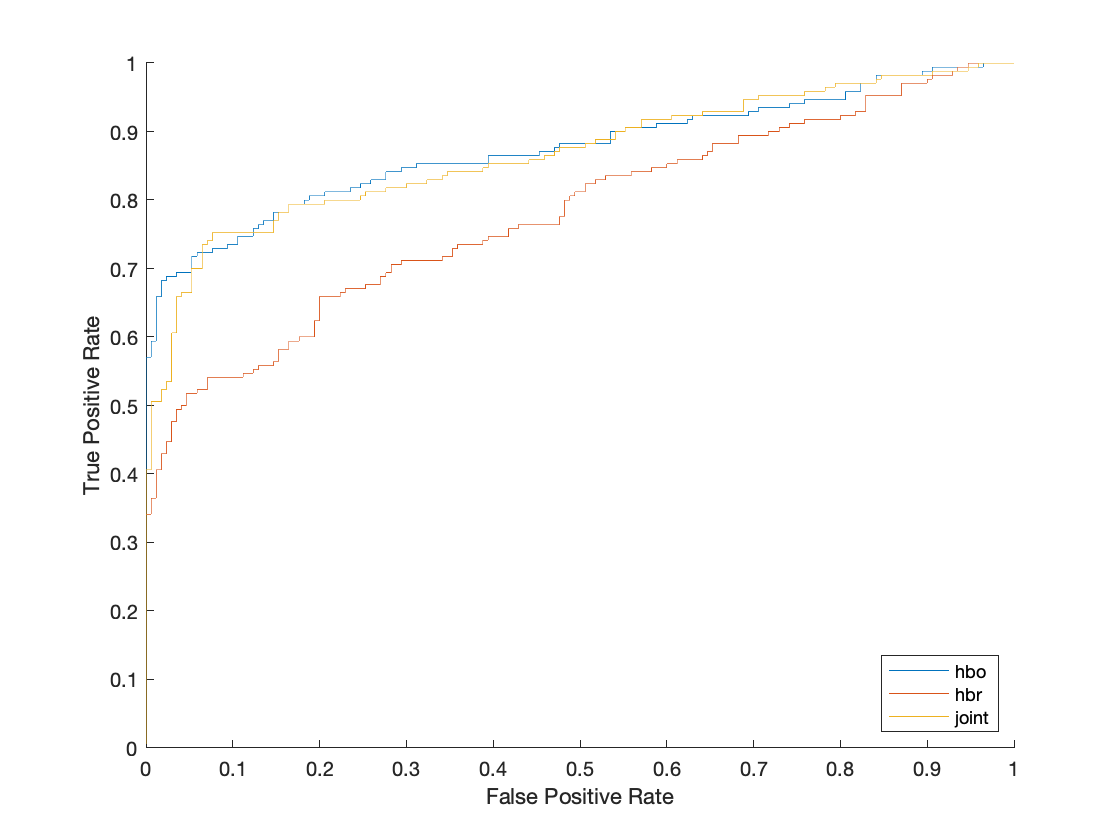

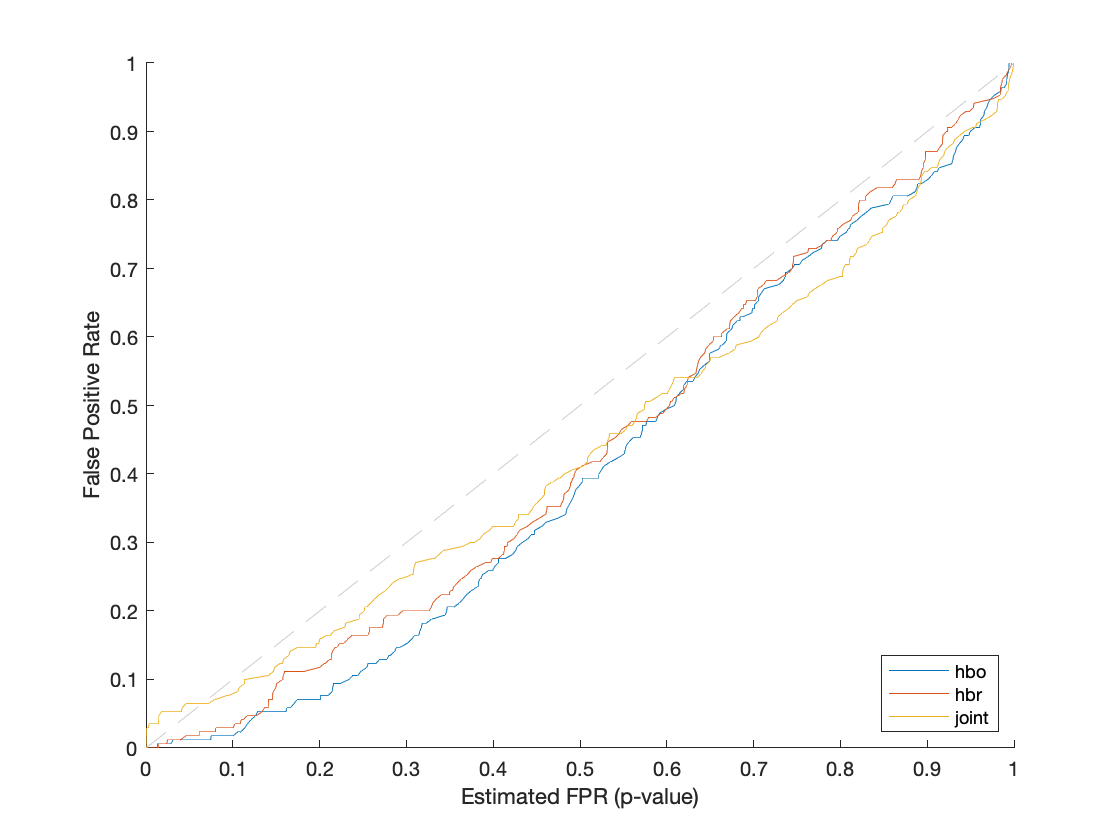


ROCtest.draw;

% This will plot two figures.  
% FIgure 1- is a ROC curve
% Figure 2- is a plot of the estimated vs. true p-value (ideally a line of
% slope =1)

% If we make the call again, it will run an additional #iterations and
% concatinate the results.  The more iterations, the more accurate the
% solution
ROCtest=ROCtest.run(num_iter);

Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 1
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 2
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 3
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 4
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Finished iter: 5
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 o

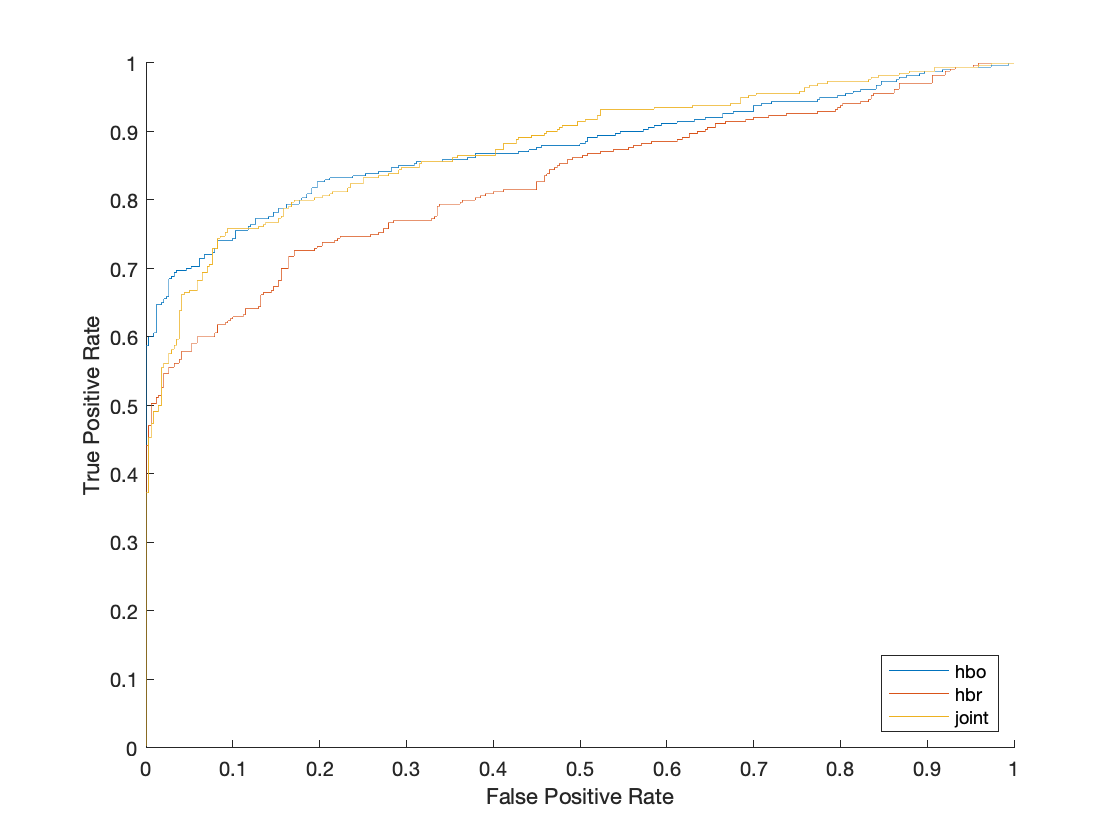

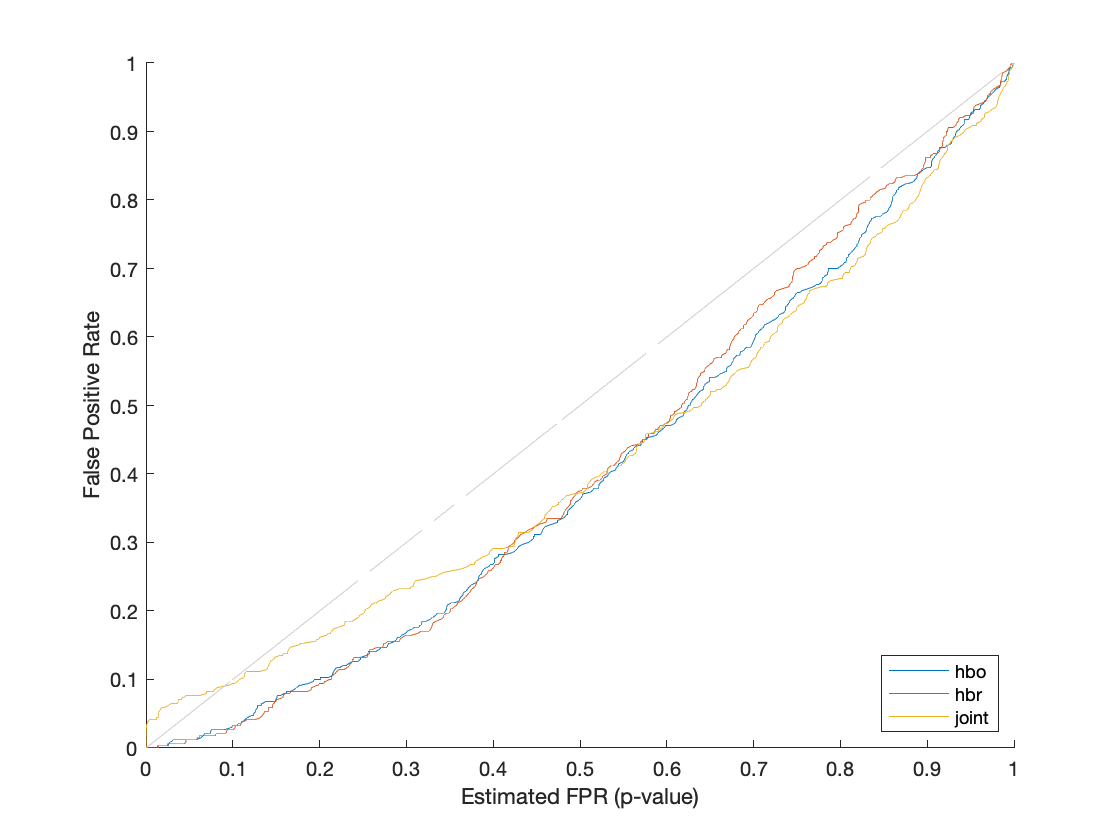


ROCtest.draw;

## Let's try to run this again with the OLS regrssion model

disp('--------------------------------------------------------------------');

--------------------------------------------------------------------


disp('PART 3:  Comparision of AR-iRLS and OLS Regression Demo');

PART 3:  Comparision of AR-iRLS and OLS Regression Demo



% Create a new model
ROCtest=nirs.testing.ChannelStatsROC;
% Add the data to the pipeline
ROCtest.simfunc=@()nirs.testing.simData(raw(randi(length(raw),1,1)));

% Create our job to test
% First the AR-IRLS job
jobs = nirs.modules.default_modules.single_subject;
ROCtest.pipeline=jobs;

%Then add the OLS job
List=nirs.modules.pipelineToList(jobs);

% But, now, lets replace the AR-IRLS with an ordinary least squares
List{9}=nirs.modules.OLS;
jobs = nirs.modules.listToPipeline(List);
ROCtest.pipeline(2)=jobs;
% Placing a second job in the array will run both jobs for comparision

ROCtest=ROCtest.run(num_iter);

Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Import data module skipped: Data prFinished    1 of    1.
SubjStats created in workspace
Finished iter: 1
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Import data module skipped: Data prFinished    1 of    1.
SubjStats created in workspace
Finished iter: 2
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Import data module skipped: Data prFinished    1 of    1.
SubjStats created in workspace
Finished iter: 3
Import data module skipped: Data provided
Hb created in workspace
.......................................Finished    1 of    1.
SubjStats created in workspace
Import data module skipped: Data prFinished   

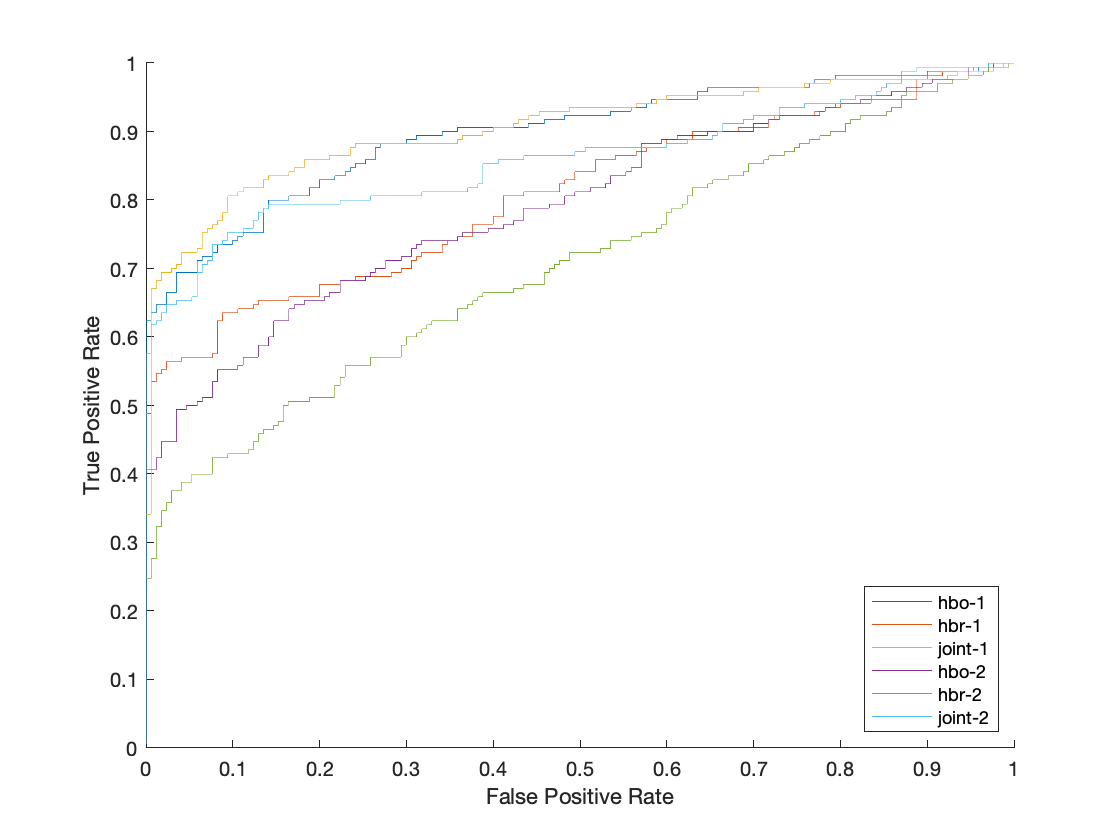

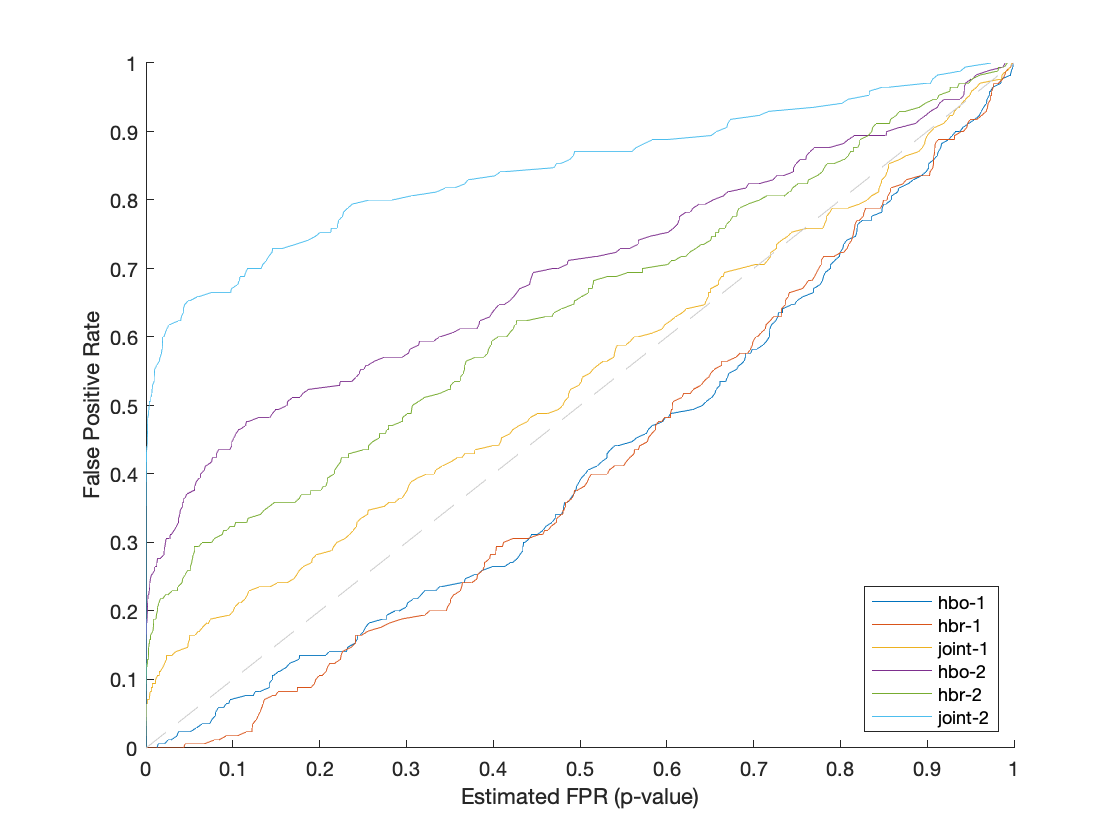

ROCtest.draw;

## Let's finally look at a group-level ROC example

disp('--------------------------------------------------------------------');

--------------------------------------------------------------------


disp('PART 4:  Group-level ROC Demo');

PART 4:  Group-level ROC Demo



%create the ROC class object
ROCtest=nirs.testing.ChannelStatsROC;
%create the data simuator (we will use all the defaults here)
ROCtest.simfunc=@()nirs.testing.simDataSet;  
%Create the pipeline to test (we will use our default group level pipeline)
ROCtest.pipeline=nirs.modules.default_modules.group_analysis;
% Run the ROC test
ROCtest=ROCtest.run(num_iter);

Import data module skipped: Data provided
Hb created in workspace
.Finished    1 of   30.
.Finished    2 of   30.
.Finished    3 of   30.
.Finished    4 of   30.
.Finished    5 of   30.
.Finished    6 of   30.
.Finished    7 of   30.
.Finished    8 of   30.
.Finished    9 of   30.
.Finished   10 of   30.
.Finished   11 of   30.
.Finished   12 of   30.
.Finished   13 of   30.
.Finished   14 of   30.
.Finished   15 of   30.
.Finished   16 of   30.
.Finished   17 of   30.
.Finished   18 of   30.
.Finished   19 of   30.
.Finished   20 of   30.
.Finished   21 of   30.
.Finished   22 of   30.
.Finished   23 of   30.
.Finished   24 of   30.
.Finished   25 of   30.
.Finished   26 of   30.
.Finished   27 of   30.
.Finished   28 of   30.
.Finished   29 of   30.
.Finished   30 of   30.
SubjStats created in workspace
GroupStats created in workspace
Finished iter: 1
Import data module skipped: Data provided
Hb created in workspace
.Finished    1 of   30.
.Finished    2 of   30.
.Finished    3 of   

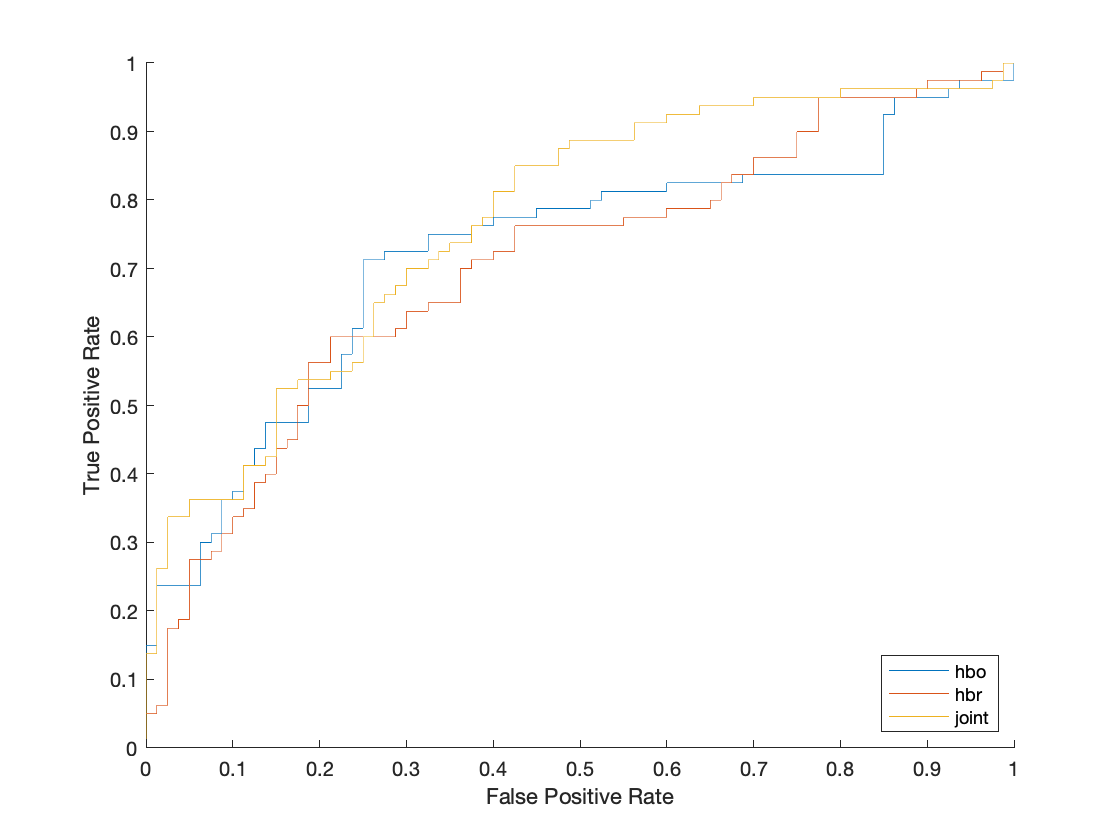

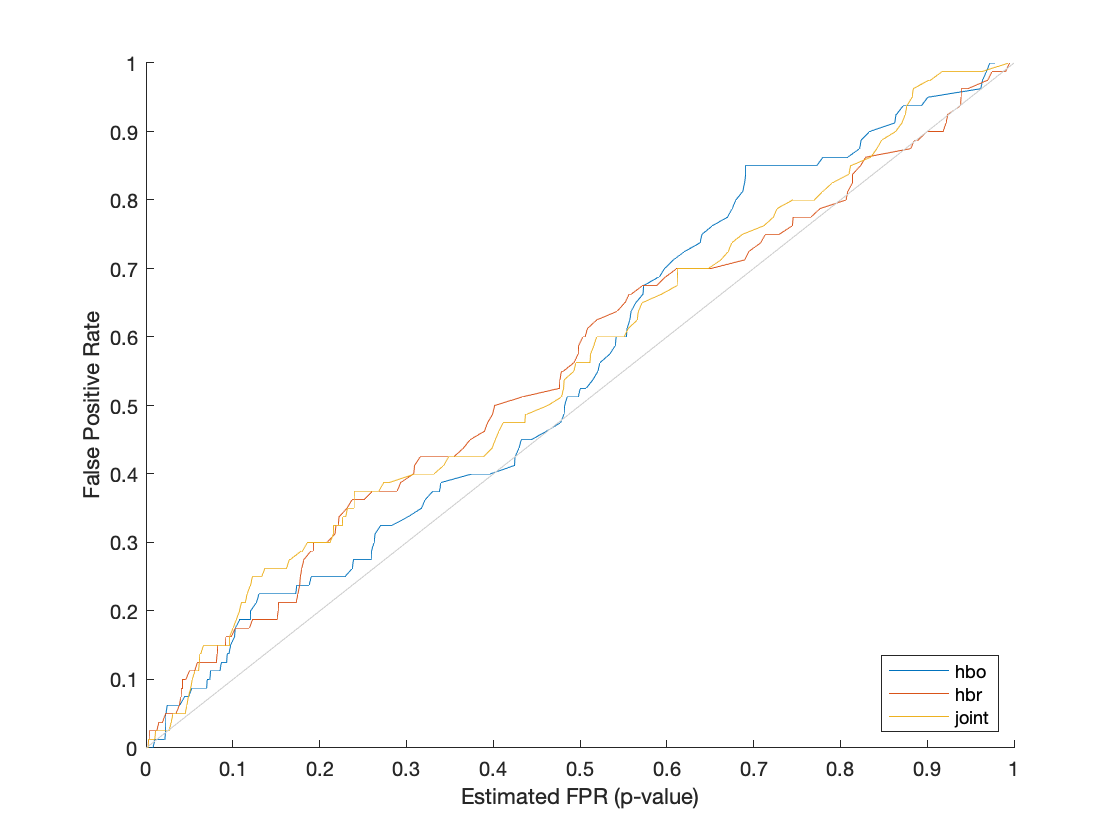

% And show the results.
ROCtest.draw;